# **Trayectorias**

Se comienza por establecer los arcos que establecen el rango.

thetaMin = linspace(0,360,100);
rMin = sqrt(2)*90;
xRanMin = -rMin*cosd(thetaMin);
yRanMin = rMin*sind(thetaMin);
rMax = sqrt(2)*200;
thetaMax = linspace(0,360,100);
xRanMax = -rMax*cosd(thetaMax);
yRanMax = rMax*sind(thetaMax);
N = 5;

## Trayectorias

### Triángulo

xiT = 100;
yiT = -100;
Len = 50;
[xT, yT] = triEq(xiT,yiT,Len,N);

### Círculo

xCC = 160;
yCC = 130;
R = 50;
[xC, yC] = circleDiscrete(xCC,yCC,R,8);

## Letras

s = 20;
xF = 170;
yF = s+10;
[xL, yL] = FINLetter(xF,yF,20,N);

## Líneas Paralelas

Largo = s*3 + 30;
[xP, yP] = Parallel(xF+10+2*s,yF,s,Largo,N);

## Puntos

[xDots, yDots] = Dots(50,140,20,5);

## Gráfica

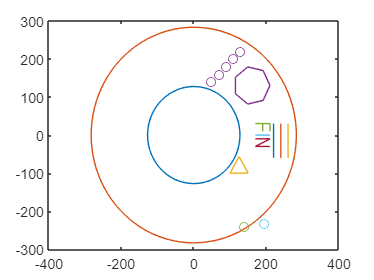

plot(xRanMin,yRanMin)
hold on
plot(xRanMax,yRanMax)
plot(xT,yT)
plot(xC, yC)
plot(xL(1:5*N),yL(1:5*N))
plot(xL(5*N+1:7*N),yL(5*N+1:7*N))
plot(xL(7*N+1:10*N),yL(7*N+1:10*N))
plot(xP(1:N),yP(1:N))
plot(xP(N+1:2*N),yP(N+1:2*N))
plot(xP(2*N+1:3*N),yP(2*N+1:3*N))
plot(xDots,yDots,'o')
plot(140,-240,'o')
plot(junaferdorilon*cosd(50),-junaferdorilon*sind(50),'o')

## Posiciones articulares

q0 = [0,0,0,0,-0.15]

q0 =          0         0         0         0   -0.1500


q0Op = [0,0,0,0,0.3]

q0Op =          0         0         0         0    0.3000


### **Recolección del marcador**

px = 140;
py = -240;
zp = 80;
qRecoleccion = zeros(6,5);
qRecoleccion(1,:) = q0Op;
junaferdorilon=215*sqrt(2)

junaferdorilon = 304.0559

zsi=20

zsi = 20

[q1,q2,q3,q4,q5]=phinv(junaferdorilon*cosd(50),-junaferdorilon*sind(50),110,0.2)

q1 = -0.8727

q2 = -0.8382

q3 = 0.9539

q4 = 0.0588

q5 = 0.2000

[q1,q2,q3,q4,q5]=phinv(junaferdorilon*cosd(50-100),-junaferdorilon*sind(50-100),120,0.2)

q1 = 0.8727

q2 = -0.8333

q3 = 1.0440

q4 = -0.0362

q5 = 0.2000

param = [[px,py,zp+100,0.3];[px,py,zp,0.3];[px,py,zp,-0.15];[px,py,zp+100,-0.15]];
for i = 1:4
    [q1, q2, q3, q4, q5] = phinv(param(i,1), param(i,2), param(i,3), param(i,4));
    qRecoleccion(i+1,:) = [q1, q2, q3, q4, q5];
end
qRecoleccion(6,:) = q0;
csvwrite('qRecolecccion.csv',qRecoleccion);

### **Dejado del marcador**

qDejado = (fliplr(qRecoleccion'))';
csvwrite('qDejado.csv',qDejado);

## Triángulo Equilátero

qTriangle = zeros(length(xT)+4,5);
qTriangle(1,:) = q0;
qTriangle(end,:) = q0;
zT = 80;
for i = 2:length(qTriangle)-1
    if(i==2)
        param = [xT(1), yT(1), zT+50,-0.15];
    elseif(i==(length(qTriangle)-1))
        param = [xT(end), yT(end), zT+50,-0.15];
    else
        param = [xT(i-2), yT(i-2), zT,-0.15];
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    qTriangle(i,:) = [q1, q2, q3, q4, q5];
end
qTriangle;
csvwrite('qTriangle.csv',qTriangle);

### Círculo

qCircle = zeros(length(xC)+4,5);
qCircle(1,:) = q0;
qCircle(end,:) = q0;
zC = 80;

for i = 2:length(qCircle)-1
    if(i==2)
        param = [xC(1), yC(1), zC+50,-0.15];
    elseif(i==(length(qCircle)-1))
        param = [xC(end), yC(end), zC+50,-0.15];
    else
        param = [xC(i-2), yC(i-2), zC,-0.15];
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    qCircle(i,:) = [q1, q2, q3, q4, q5];
end
qCircle;
csvwrite('qCircle.csv',qCircle);

## Letras

qLetter = zeros(length(xL)+8,5);
qLetter(1,:) = q0;
qLetter(end,:) = q0;
zL = 80;
j = 1;
for i = 2:length(qLetter)-1
    if((i==2)||(i==(4+5*N))||(i==(6+7*N)))
        param = [xL(j), yL(j), zL+50,-0.15];
    elseif((i==(3+5*N))||(i==(5+7*N)))
        param = [xL(j-1), yL(j-1), zL+50,-0.15];
    elseif(i==(length(qLetter)-1))
        param = [xL(end), yL(end), zL+50,-0.15];
    else
        param = [xL(j), yL(j), zL,-0.15];
        j = j+1;
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    qLetter(i,:) = [q1, q2, q3, q4, q5];
end
qLetter;
csvwrite('qLetter.csv',qLetter);

## Líneas Paralelas

qPar = zeros(length(xP)+8,5);
qPar(1,:) = q0;
qPar(end,:) = q0;
zP = 80;
j = 1;
for i = 2:length(qPar)-1
    if((i==2)||(i==(4+N))||(i==(6+2*N)))
        param = [xP(j), yP(j), zP,-0.15];
    elseif((i==(3+N))||(i==(5+2*N)))
        param = [xP(j-1), yP(j-1), zP,-0.15];
    elseif(i==(length(qPar)-1))
        param = [xP(end), yP(end), zp,-0.15];
    else
        param = [xP(j), yP(j), zP,-0.15];
        j = j+1;
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    if((i==(length(qPar)-1))||(i==(3+N))||(i==(5+2*N))||(i==(4+N))||(i==(6+2*N)))
    qPar(i,:) = [q1, q2+pi/6, q3, q4, q5];
    else
    qPar(i,:) = [q1, q2, q3, q4, q5];
    end

end
qPar;
csvwrite('qPar.csv',qPar);

## Puntos

qDots = zeros(3*length(xDots)+2,5);
qDots(1,:) = q0;
qDots(end,:) = q0;
zD = 80;
j = 1;
for i = 1:5
    for j=1:3
        if(j==1)
            param = [xDots(i), yDots(i), zD+50,-0.15];
        elseif(j==2)
            param = [xDots(i), yDots(i), zD,-0.15];
        elseif(j==3)
            param = [xDots(i), yDots(i), zD+50,-0.15];    
        end
        [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
        qDots((i-1)*3+(j-1)+2,:) = [q1, q2, q3, q4, q5];
    end
end
qDots

qDots =          0         0         0         0   -0.1500
    1.2278    0.7639   -1.3302    0.7409   -0.1500
    1.2278   -0.1250   -1.4305    1.7300   -0.1500
    1.2278    0.7639   -1.3302    0.7409   -0.1500
    1.1584    0.4913   -1.0984    0.7815   -0.1500
    1.1584   -0.1148   -1.1713    1.4606   -0.1500
    1.1584    0.4913   -1.0984    0.7815   -0.1500
    1.1071    0.2692   -0.8290    0.7344   -0.1500
    1.1071   -0.1839   -0.8881    1.2466   -0.1500
    1.1071    0.2692   -0.8290    0.7344   -0.1500


csvwrite('qDots.csv',qDots);